# TMS Data Analysis

This example shows you how to import and decode CAN data from BLF-files in MATLAB for analysis. The BLF-file used in this example was generated from the DEV1 testbench.

## Open the DBC-File

Open the database file describing the source CAN network using the [`canDatabase`](https://www.mathworks.com/help/vnt/ug/candatabase.html) function.

tld = pwd;
cd ../Databases/
% canDB = canDatabase(tld + "\Databases\" + "TMS_NODE2.dbc");
canDB = canDatabase("TMS_NODE2.dbc");

## Investigate the BLF-File

Retrieve and view information about the BLF-File. The [`blfinfo`](https://www.mathworks.com/help/vnt/ug/blfinfo.html) function parses general information about the format and contents of the Vector Binary Logging Format BLF-file and returns the information as a structure.

filename = "test101022-2.blf";
cd ../Logs/
binf = blfinfo(filename);
% binf = blfinfo(tld + "\Logs\" + filename);
% binf.ChannelList

## Read Data from mat-File

The data of interest was logged from the powertrain bus which is stored in channel 2 of the BLF-file. Read the CAN data using the [`blfread`](https://www.mathworks.com/help/vnt/ug/blfread.html) function. You can also provide the DBC-file to the function call which will enable message name lookup and signal value decoding.

cd ../Logs/
% blfData = blfread(filename, 1, "Database", canDB);
% blfData = blfread(tld + "\Logs\" + filename, 1, "Database", canDB);
filename = "test_10_13_10k.mat";
cd ../Logs/
% load(tld + "\Logs\" + filename);
load(filename);

## Repackage and Visualize Signal Values of Interest

Use the [`canSignalTimetable`](https://www.mathworks.com/help/vnt/ug/cansignaltimetable.html) function to repackage signal data from each unique message on the bus into a signal timetable. This example creates three individual signal timetables for the three messages of interest, "ABSdata", "EngineData" and "GearBoxInfo", from the CAN message timetable.

signalTimetable1 = canSignalTimetable(rxData, "TMS_PDO_1");
signalTimetable2 = canSignalTimetable(rxData, "TMS_PDO_2");
signalTimetable3 = canSignalTimetable(rxData, "TMS_PDO_3");
signalTimetable4 = canSignalTimetable(rxData, "TMS_PDO_4");


To visualize the signals of interest, columns from the signal timetables can be plotted over time for further analysis.

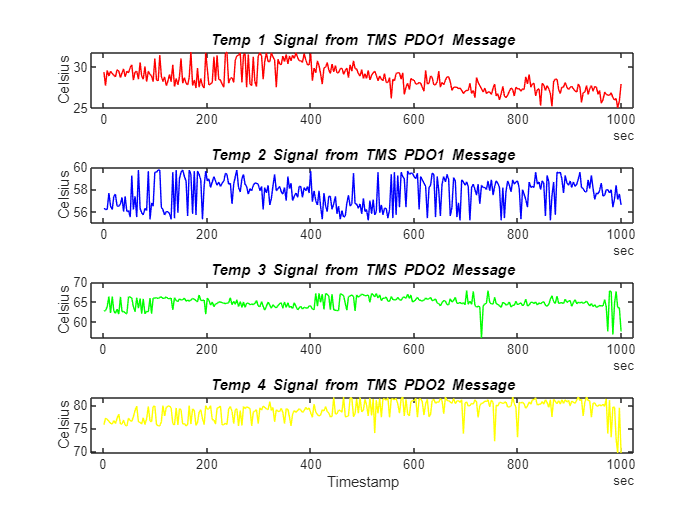

subplot(4, 1, 1)
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
title("{\itTemp 1} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Celsius")
subplot(4, 1, 2)
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
title("{\itTemp 2} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Celsius")
subplot(4, 1, 3)
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
title("{\itTemp 3} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Celsius")

subplot(4, 1, 4)
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
title("{\itTemp 4} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
xlabel("Timestamp")
ylabel("Celsius")

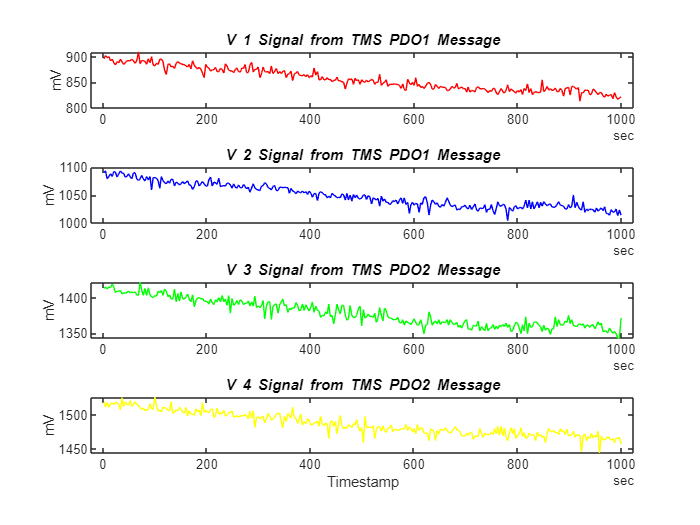


figure
subplot(4, 1, 1)
plot(signalTimetable3.Time, signalTimetable3.V1, "r")
title("{\itV 1} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("mV")
subplot(4, 1, 2)
plot(signalTimetable3.Time, signalTimetable3.V2, "b")
title("{\itV 2} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("mV")
subplot(4, 1, 3)
plot(signalTimetable4.Time, signalTimetable4.V3, "g")
title("{\itV 3} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("mV")

subplot(4, 1, 4)
plot(signalTimetable4.Time, signalTimetable4.V4, "y")
title("{\itV 4} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
xlabel("Timestamp")
ylabel("mV")

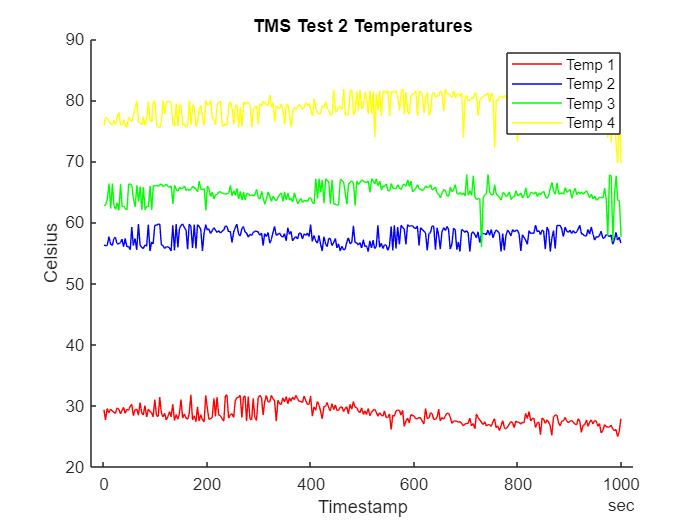

figure
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
legend("Temp 1", "Temp 2", "Temp 3", "Temp 4")
xlabel("Timestamp")
ylabel("Celsius")

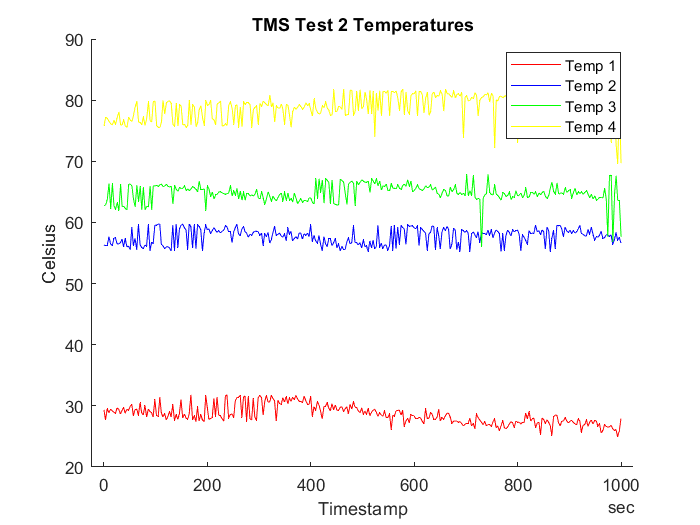


figure
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
legend("Temp 1", "Temp 2", "Temp 3", "Temp 4")
xlabel("Timestamp")
ylabel("Celsius")

Get NI data

% filename = "test101022-2.mat";
% cd ../Logs/
% % load(tld + "\Logs\" + filename);
% load(filename);

nidata = horzcat(time, data)

nidata =          0   23.9162   23.0896    3.3691    1.6608    3.3305    1.6011    1.3774
    0.0714   23.9162   23.0896    3.3726    1.6627    3.3308    1.6020    0.8106
    0.1429   23.9162   23.0896    3.3732    1.6554    3.3305    1.6030    0.5647
    0.2143   23.8232   23.0905    3.3723    1.6570    3.3308    1.6017    0.4602
    0.2857   23.8232   23.0905    3.3726    1.6532    3.3292    1.6027    1.0403
    0.3571   23.8232   23.0905    3.3726    1.6576    3.3289    1.6024    0.6730
    0.4286   23.8638   23.1138    3.3729    1.6589    3.3286    1.6008    0.5032
    0.5000   23.8638   23.1138    3.3723    1.6589    3.3308    1.6049    1.4057
    0.5714   23.8638   23.1138    3.3729    1.6586    3.3292    1.6024    0.8243
    0.6429   23.9855   23.1088    3.3729    1.6602    3.3292    1.6030    0.5713


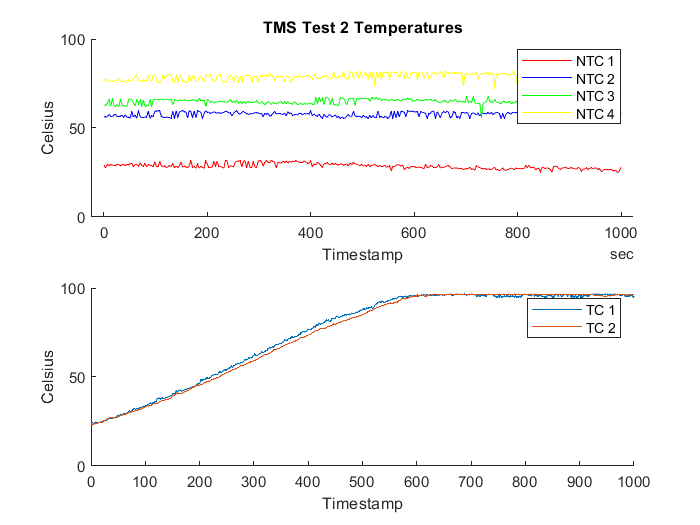

figure
hold on
% title("TMS Test 2 Temperatures")
subplot(2,1,1)
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
legend("NTC 1", "NTC 2", "NTC 3", "NTC 4")
% xlim([0, 1000])
ylim([0 100])
xlabel("Timestamp")
ylabel("Celsius")
subplot(2,1,2)
hold on
plot(nidata(:,1), nidata(:,2))
plot(nidata(:,1), nidata(:,3))
% xlim([0, 1000])
ylim([0 100])
legend("TC 1", "TC 2");
xlabel("Timestamp")
ylabel("Celsius")

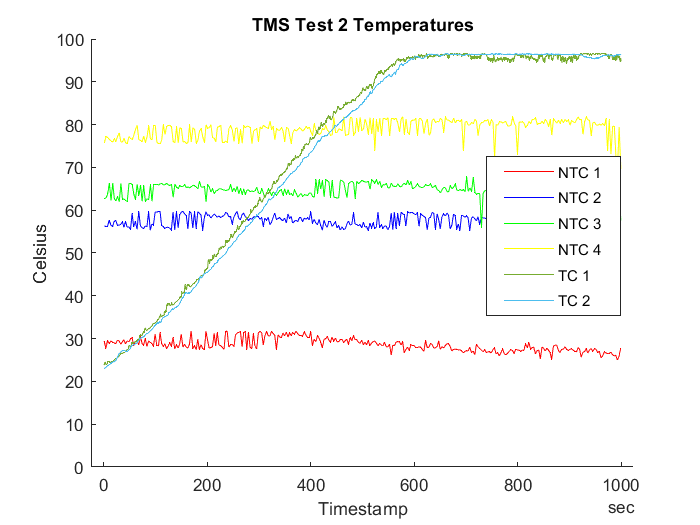


figure
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
plot(nidata(:,1), nidata(:,2))
plot(nidata(:,1), nidata(:,3))
ylim([0 100])
legend("NTC 1", "NTC 2", "NTC 3", "NTC 4", "TC 1", "TC 2");
legend('Position',[0.69395,0.39736,0.19275,0.30579])
xlabel("Timestamp")
ylabel("Celsius")

NTC 1

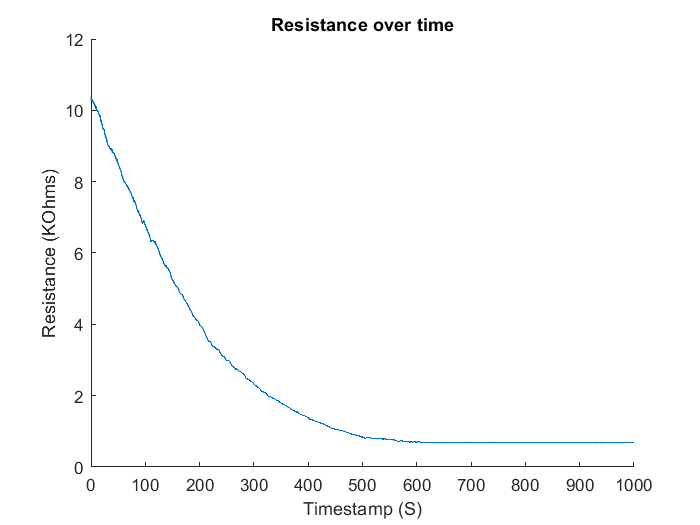

r1 = 10000;
vdd = nidata(:,4);
vdiv = nidata(:,5);
rntc = (vdd*r1)./(vdiv)-r1;

figure
hold on
title("Resistance over time")
plot(nidata(:,1), rntc/1000)
xlabel("Timestamp (S)")
ylabel("Resistance (KOhms)")

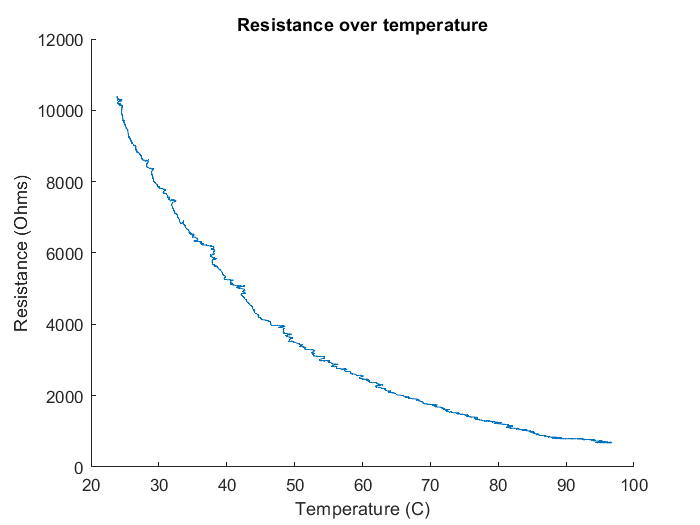

figure
hold on
title("Resistance over temperature")
plot(nidata(:,2),rntc)
xlabel("Temperature (C)")
ylabel("Resistance (Ohms)")

Smooth data

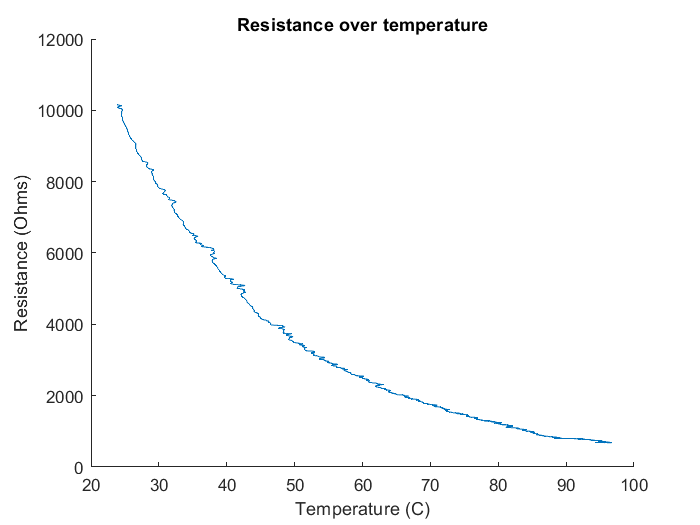

% Smooth input data
sm_ntc = smoothdata(rntc,"gaussian","SmoothingFactor",0.05);
figure
hold on
title("Resistance over temperature")
plot(nidata(:,2),sm_ntc)
xlabel("Temperature (C)")
ylabel("Resistance (Ohms)")

Smooth data

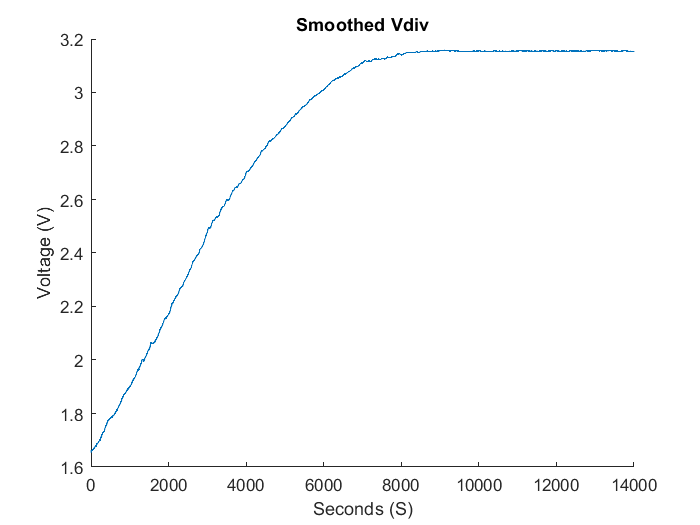

% Smooth input data
sm_vdiv = smoothdata(vdiv,"gaussian","SmoothingFactor",0.05);
figure
hold on
title("Smoothed Vdiv")
plot(vdiv)
% plot(sm_vdiv, LineWidth=3)
xlabel("Seconds (S)")
ylabel("Voltage (V)")

`C(x) = 18.352x^3-69.323x^2+121.29x-7.3735`

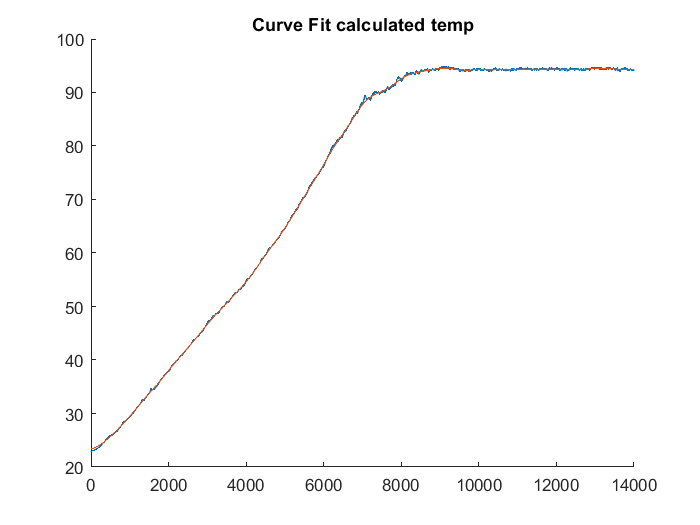

 p1 =       34.12;
 p2 =      -295.4;
 p3 =       952.7;
 p4 =       -1326;
 p5 =         691;

x = vdiv;
calc_temp = p1.*x.^4 + p2.*x.^3 + p3.*x.^2 + p4.*x + p5;

y = sm_vdiv;
calc_temp2 = p1.*y.^4 + p2.*y.^3 + p3.*y.^2 + p4.*y + p5;

figure
hold on
title("Curve Fit calculated temp")
plot(calc_temp)
plot(calc_temp2)

% plot(temp)


Residuals

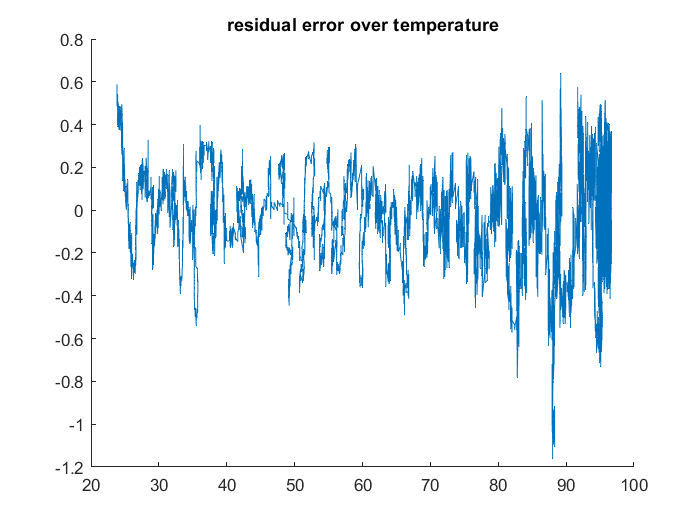

residuals = calc_temp2 - calc_temp;
figure
hold on
title("residual error over temperature")
plot(nidata(:,2),residuals)

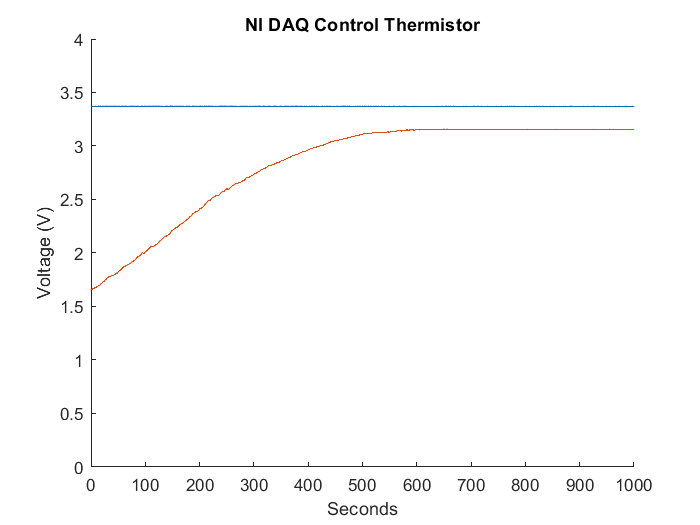

figure
hold on
plot(nidata(:,1), nidata(:,4))
plot(nidata(:,1), nidata(:,5))
ylim([0 4])
title("NI DAQ Control Thermistor")
xlabel("Seconds")
ylabel("Voltage (V)")

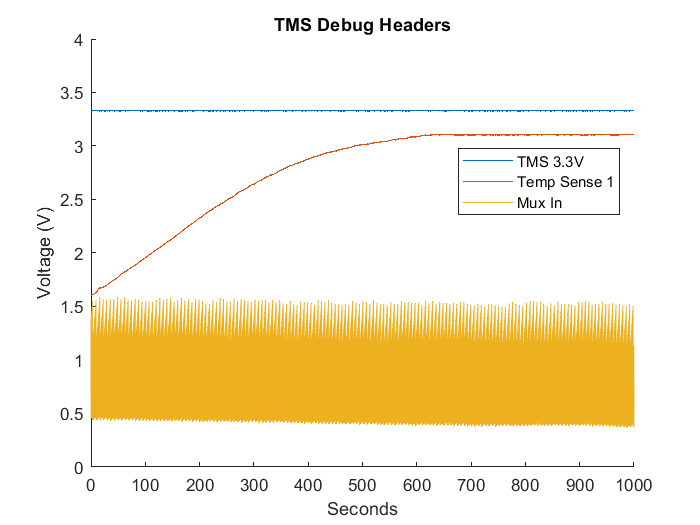


figure
hold on
plot(nidata(:,1), nidata(:,6))
plot(nidata(:,1), nidata(:,7))
plot(nidata(:,1), nidata(:,8))
ylim([0 4])
legend("TMS 3.3V", "Temp Sense 1", "Mux In")
title("TMS Debug Headers")
xlabel("Seconds")
ylabel("Voltage (V)")
legend('Position',[0.65417,0.59127,0.23107,0.12619])

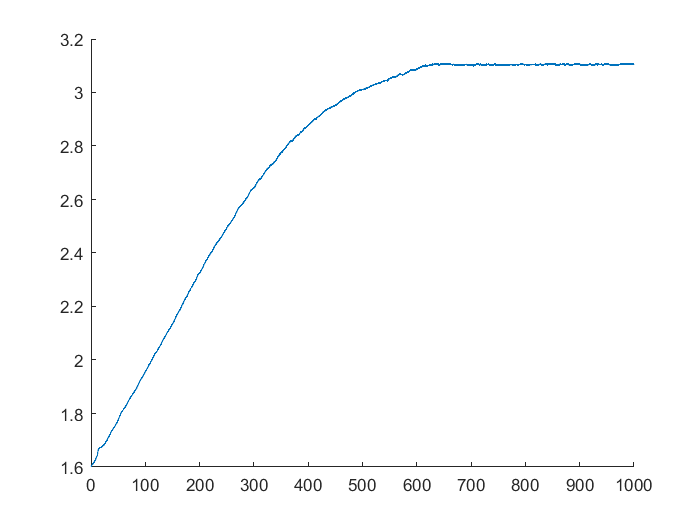

figure
hold on
plot(nidata(:,1),nidata(:,7))

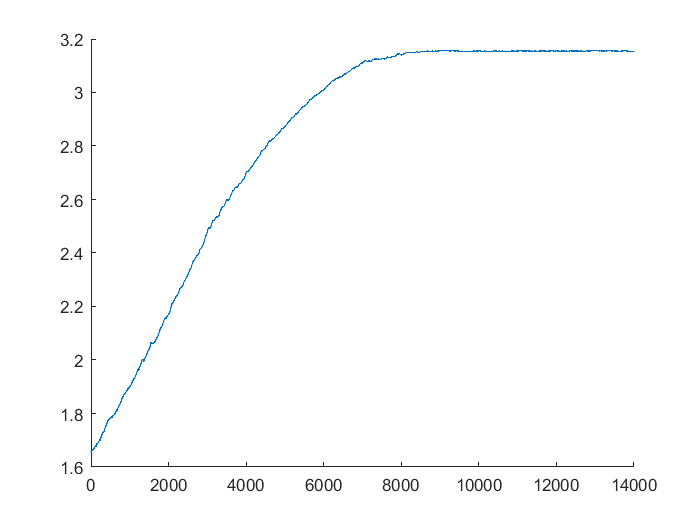

cd ../Logs/
load('temp_vdiv_from_test_10_13_10k.mat')

figure
hold on
plot(vdiv)

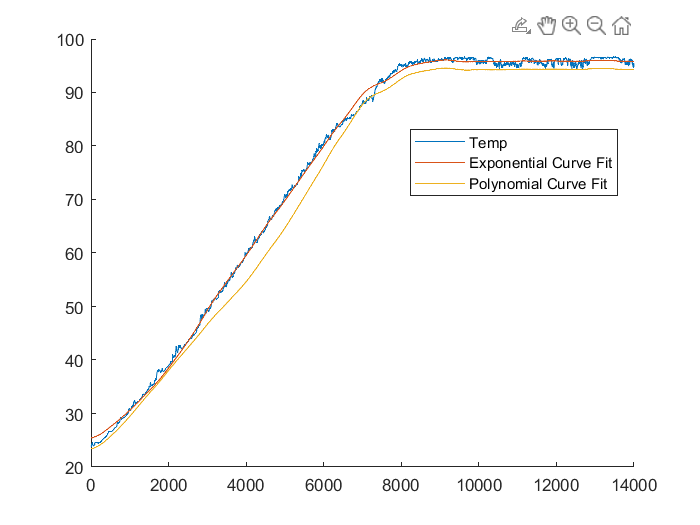

 p1 =       34.12;
 p2 =      -295.4;
 p3 =       952.7;
 p4 =       -1326;
 p5 =         691;
% 
% x = vdiv;
% calc_temp = p1.*x.^4 + p2.*x.^3 + p3.*x.^2 + p4.*x + p5;

y = sm_vdiv;
calc_temp2 = p1.*y.^4 + p2.*y.^3 + p3.*y.^2 + p4.*y + p5;

%Coefficients (with 95% confidence bounds):
       a =       6.187;  %(6.162, 6.213)
       b =      0.8397;  %(0.838, 0.8414)
       c =   3.337e-12;  %(1.097e-12, 5.577e-12)
       d =       9.049;  %(8.84, 9.258)
tempcfit = a*exp(b.*y) + c*exp(d.*y);

figure
hold on
plot(temp)
plot(tempcfit)
plot(calc_temp2)
legend("Temp", "Exponential Curve Fit", "Polynomial Curve Fit")
legend('Position',[0.5856,0.62746,0.29679,0.12619])



cd ../Scripts/